# 3. Creating Networks

load satData.mat

### Peek into the data

Note the dimensions of the data.

classes = categorical(YTrain)

classes = 6×1 cell 배열
    {'barren land'}
    {'building'   }
    {'grassland'  }
    {'road'       }
    {'trees'      }
    {'water'      }


ans =           28          28           4        3000


size(XTrain)

View the infrared channel of the 507th land cover image in grayscale

image507 = 28×28 uint8 행렬
    91   106   134   160   176   181   185   185   179   175   160   127   101    97    99   103   110   126   156   184   188   186   187   187   185   184   181   179
    89    86   103   136   159   163   172   182   187   189   171   123    87    87    90    92    92    99   121   157   179   187   187   187   186   183   180   177
    95    85    87   100   115   126   154   177   183   187   178   152   112    89    83    85    87    91    99   125   161   180   186   189   187   183   181   179
    97    95    86    87   101   131   158   169   178   183   181   177   165   128    94    87    89    91    92    99   125   161   182   188   186   183   183   180
    92    98    96    85    85   107   134   151   166   171   174   180   182   167   131   100    91    87    83    84    94   121   159   182   185   184   184   182
    90    90    95    93    82    88   107   141   155   149   146   171   180   180   175   139    93    79    67    56    62   

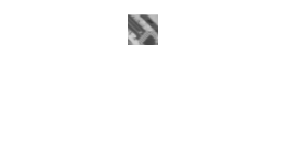

label507 = categorical
     building 


image507 = XTrain(:,:,4,507)

imshow(image507)
label507 = YTrain(507)

## Create a Network from Layers

### Create the CNN Layers

Create a column vector of 6 layers named `layers`, with the layers in the order shown below.

`imageInputLayer``(``inputSize``)`

`convolution2dLayer``(``filterSize``,``numFilters``)`

`reluLayer``()`

`maxPooling2dLayer``(``poolSize``)`

`fullyConnectedLayer``(``numClasses``)`

`softmaxLayer``()`

Use the following information to choose the inputs for the layers:

- Each image is size 28-by-28-by-4.

- The convolution layer should have a 20 filters of size 3-by-3.

- The pooling layer should have a pool size of 3-by-3.

- There are six classes.

layers = [imageInputLayer([28,28,4]);...
    convolution2dLayer([3,3],20),...
    reluLayer(); maxPooling2dLayer([3,3]);...
    fullyConnectedLayer(6); softmaxLayer();]

View the network architecture

analyzeNetwork(layers)

### Training Options

Create training options named `options`. Use the algorithm `"sgdm"`, set the maximum number of epochs to `5`, and set the initial learning rate to `0.0001`.

opts = trainingOptions("sgdm","MaxEpochs",50,...
    "InitialLearnRate",0.0001,"Plots","training-progress",...
    "Metrics","accuracy","ExecutionEnvironment","auto","Shuffle","once")

### Train the Network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:02       0.0001          10.416              28.906
           50        3       00:00:12       0.0001          1.6278                87.5
          100        5       00:00:14       0.0001         0.18738              97.656
          150        7       00:00:16       0.0001          1.2331              90.625
          200        9       00:00:18       0.0001         0.92839              92.969
          250       11       00:00:20       0.0001         0.20741              98.438
          300       14       00:00:22       0.0001         0.71924              95.312
          350       16       00:00:23       0.0001         0.72311              94.531
          400       18       00:00:25       0.0001        0.022207              98.438
          450       20       00:00:26      

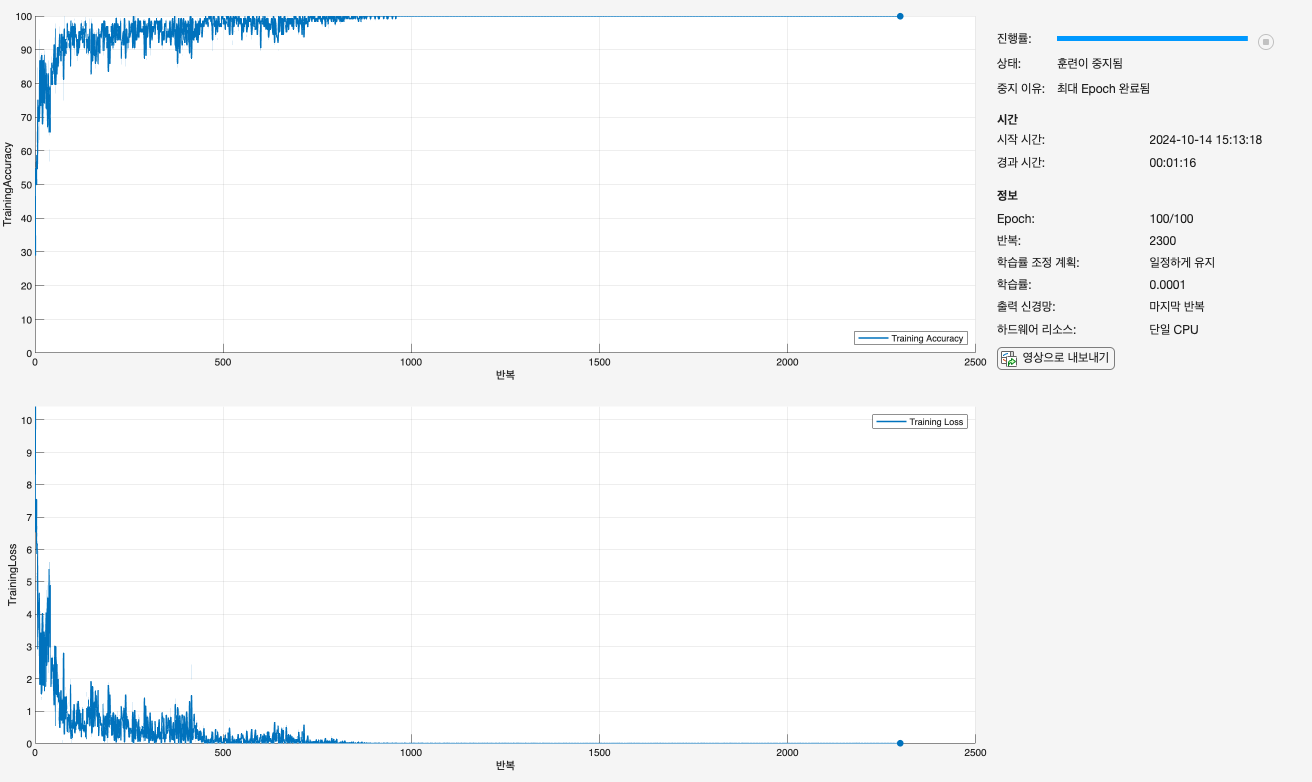

landnet =   dlnetwork - 속성 있음:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     Learnables: [4×3 table]
          State: [0×3 table]
     InputNames: {'imageinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  요약 보기(summary 참조).


landnet = trainnet(XTrain,YTrain,layers,"crossentropy",opts)

### Classify and Evaluate the Network

scores = 600×6 single 행렬
    1.0000    0.0000    0.0000    0.0000         0         0
    1.0000    0.0000    0.0000    0.0000         0         0
    1.0000    0.0000    0.0000    0.0000    0.0000         0
    1.0000         0    0.0000    0.0000         0         0
    1.0000    0.0000    0.0000    0.0000         0         0
    1.0000    0.0000    0.0000    0.0000         0         0
    1.0000         0    0.0000    0.0000         0         0
    1.0000         0    0.0000    0.0000         0         0
    1.0000    0.0000    0.0000    0.0000         0         0
    1.0000    0.0000    0.0000    0.0000         0         0


testPred = 600×1 categorical 배열
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     grassland 
     grassland 
     barren land 
     grassland 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 


score = 600×1 single 열 벡터
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


testAcc = 0.9483

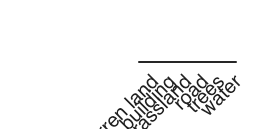

scores = minibatchpredict(landnet,XTest)

[testPred,score] = scores2label(scores,classes)
testGT = YTest
testAcc = nnz(testGT == testPred) / numel(testPred)
confusionchart(testGT,testPred)

## Convolutional Layer, Performing Convolutions

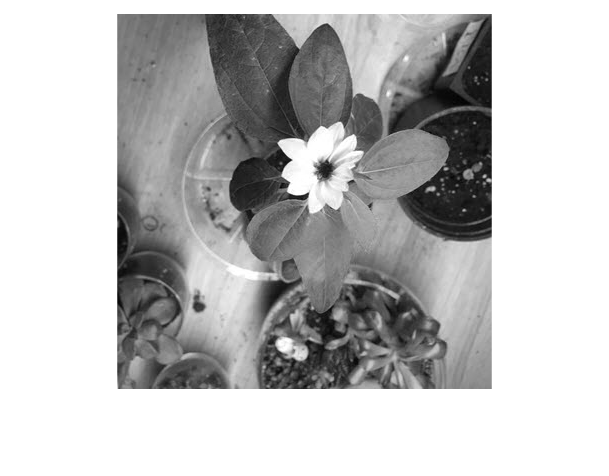

im = imread("sunflower.jpg")

redIm = im(:,:,1);
imshow(redIm)

1. Create a 3-by-3 filter(often called 'kernel') that blurs an image and use the filter with the `conv2` function.

blurKernel = 1/9*ones(3)

blurKernel =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


blurConv =    12.8889   26.3333   40.2222   41.4444   42.0000   41.8889   41.5556   41.4444   40.8889   40.2222   39.3333   39.0000   38.7778   38.7778   39.1111   39.5556   39.6667   39.7778   40.0000   40.5556   40.7778   40.4444   39.7778   39.1111   38.0000   37.3333   37.1111   37.8889   38.5556   38.7778   38.5556   38.0000   37.2222   36.5556   36.0000   35.7778   35.6667   35.7778   36.0000   36.3333   36.7778   37.7778   39.0000   39.5556   39.1111   38.3333   38.0000   37.7778   37.5556   37.1111
   25.7778   52.5556   80.3333   82.6667   83.7778   83.4444   82.7778   82.5556   81.4444   80.2222   78.5556   78.1111   77.7778   77.8889   78.3333   79.0000   79.2222   79.5556   79.8889   80.6667   81.1111   80.7778   79.5556   77.8889   75.2222   73.6667   73.2222   74.7778   76.1111   76.6667   76.3333   75.4444   74.2222   73.2222   72.3333   71.7778   71.4444   71.5556   72.0000   72.5556   73.4444   75.3333   77.7778   78.7778   77.8889   76.4444   75.8889   75.5556   75.00

blurConv = conv2(blurKernel,redIm)

View the result using `imshow` function. Note that it is often useful to use a second argument to imshow when displaying grayscale images. Using empty brackets as the second input will scale the display based on the minimum and maximum values present in the image.

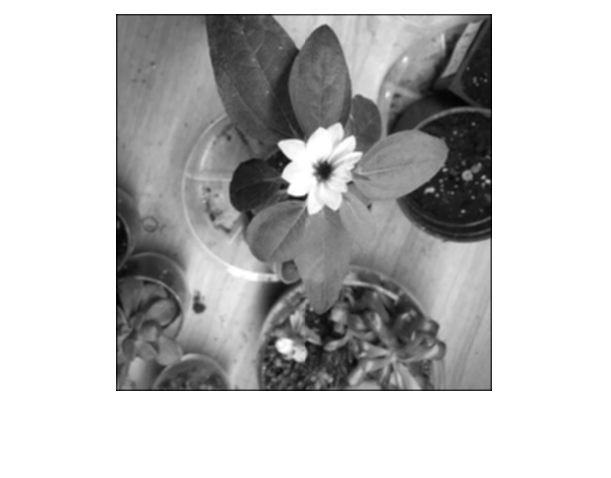

imshow(blurConv,[]) % imshow(rescale(blurConv))

2. Create a 3-by-3 filter that detects edges and use the filter.

edgeKernel =      0     1     0
     1    -4     1
     0     1     0


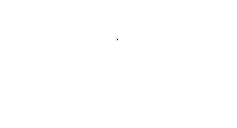

edgeKernel = [0 1 0; 1 -4 1; 0 1 0]

edgeConv = conv2(edgeKernel,redIm);
imshow(edgeKernel,[])

## Viewing Learned Filters

Load and display an image with different colored flowers.

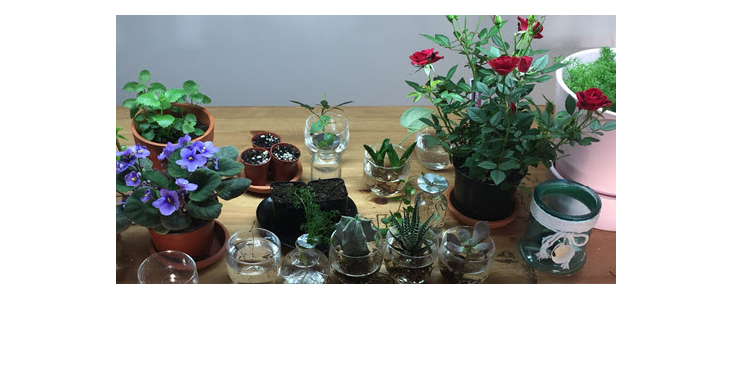

im = imread("roses.jpg")

imshow(im)

Load GoogLeNet and saves the layers in a variable

net = imagePretrainedNetwork("googlenet")

layers =   다음 계층을 포함한 143×1 Layer 배열:

     1   'data'                           영상 입력              224×224×3 영상 (정규화: 'zerocenter')
     2   'conv1-7x7_s2'                   2차원 컨벌루션          64개 7×7×3 컨벌루션(스트라이드: [2  2], 채우기: [3  3  3  3])
     3   'conv1-relu_7x7'                 ReLU                  ReLU
     4   'pool1-3x3_s2'                   2차원 최댓값 풀링       3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  1  0  1])
     5   'pool1-norm1'                    교차 채널 정규화        교차 채널 정규화 (요소당 채널 5개)
     6   'conv2-3x3_reduce'               2차원 컨벌루션          64개 1×1×64 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     7   'conv2-relu_3x3_reduce'          ReLU                  ReLU
     8   'conv2-3x3'                      2차원 컨벌루션          192개 3×3×64 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
     9   'conv2-relu_3x3'                 ReLU                  ReLU
    10   'conv2-norm2'                    교차 채널 정규화        교차 채널

layers = net.Layers
analyzeNetwork(net)
% analyzeNetwork(layers)

The `Weights` property of a layer contains that layer's weights. Weights are learned during training. Since GoogLeNet is a pretrained network, it has already learned weights that will find useful features. In this activity, you will inspect these weights in more detail.

Save the weights of the second layer to a variable and view the array of weights

You can view a specific filter by indexing into the weights. Extract the eleventh filter from the array of weights, then display it.

weightLayer2 = 7×7×3×64 single 배열
weightLayer2(:,:,1,1) =

    0.2290    0.1553   -0.0366   -0.2719   -0.2654   -0.1182   -0.0461
    0.0798   -0.0726   -0.2621   -0.4031   -0.3669   -0.0964    0.0031
   -0.0413   -0.1354   -0.2717   -0.4117   -0.1016    0.2899    0.2039
   -0.0976   -0.1944   -0.3115   -0.1588    0.4638    0.4693    0.0925
   -0.0791   -0.1483   -0.0779    0.2429    0.4363    0.1472   -0.0853
   -0.0377   -0.0296    0.0476    0.1915    0.1772   -0.0638   -0.1631
   -0.0261   -0.0119    0.0705    0.1137    0.0325   -0.1288   -0.1103


weightLayer2(:,:,2,1) =

   -0.2536   -0.1480   -0.0368    0.0830    0.1555    0.1493    0.0695
   -0.1202   -0.0393    0.1203    0.2832    0.2575    0.1918    0.0806
   -0.0390    0.1019    0.2608    0.2753    0.2314    0.2532    0.0917
    0.0741    0.1887    0.1857    0.2352    0.3369    0.1195   -0.0961
    0.1060    0.1308    0.1429    0.2124    0.0077   -0.1950   -0.1899
    0.0730    0.0977    0.0636   -0.0056   -0.1647   -0.1989  

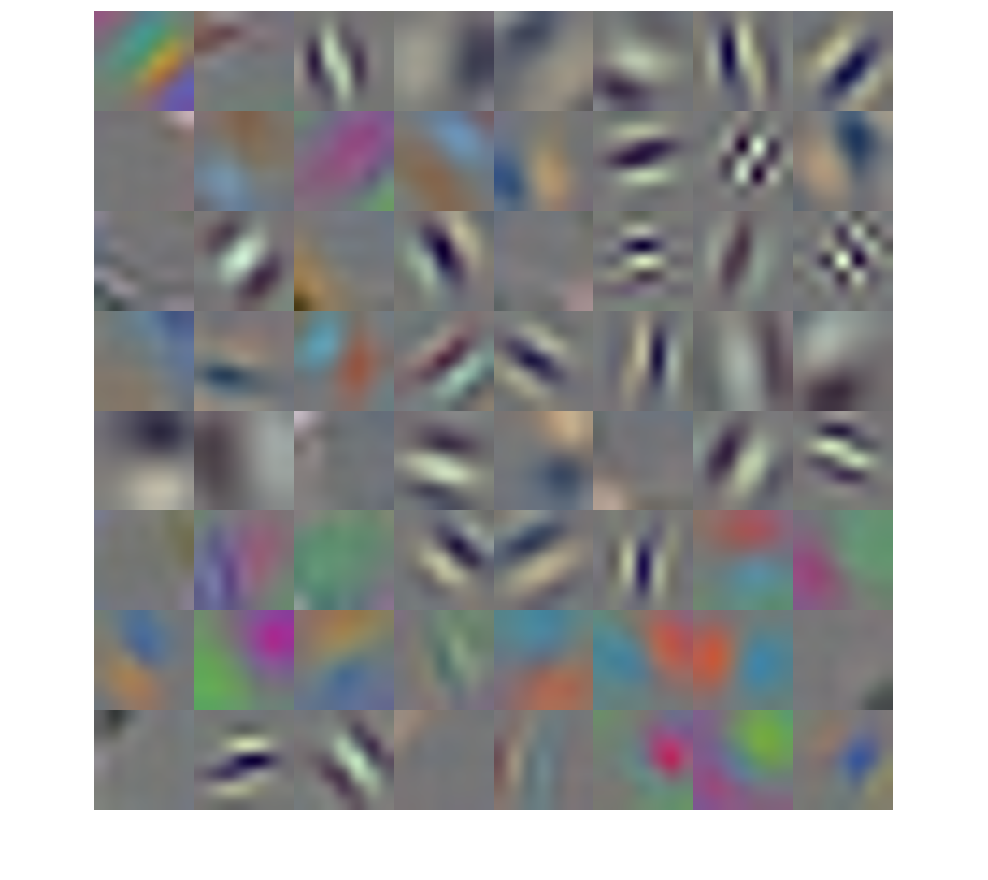

The eleventh filter seems to be looking for the color pink. The image roses.jpg contains a few plants, but only the roses are red. Hence, only the roses should be positively activated from the eleventh filter.

Let's see the eleventh filter actually activate the pink color from the image.

filter11 = 7×7×3 single 배열
filter11(:,:,1) =

   -0.0895   -0.0768   -0.0711    0.0394    0.1457    0.1333    0.0374
   -0.0858   -0.0485    0.0319    0.1247    0.2044    0.1512    0.1153
    0.0131    0.0410    0.1294    0.2090    0.2309    0.2007    0.0372
    0.0693    0.1165    0.1452    0.2312    0.2651    0.1012   -0.0704
    0.1196    0.1071    0.1481    0.1838    0.1287   -0.1380   -0.0765
    0.0737    0.1045    0.0933    0.0561   -0.0618   -0.1546   -0.0579
    0.1044    0.0729    0.0251   -0.0337   -0.0919   -0.1056   -0.0967


filter11(:,:,2) =

    0.1227    0.0489   -0.0739   -0.1725   -0.1990   -0.2691   -0.2370
   -0.0060   -0.0696   -0.1463   -0.2959   -0.3655   -0.4032   -0.2355
   -0.0192   -0.1180   -0.1866   -0.3524   -0.3817   -0.3189   -0.2582
   -0.0891   -0.1745   -0.2783   -0.3255   -0.2351   -0.2622   -0.1885
   -0.1270   -0.2314   -0.2528   -0.2432   -0.1733   -0.2647    0.0268
   -0.1566   -0.1564   -0.1539   -0.1306   -0.0973   -0.0127    0.2421
   -0.0558